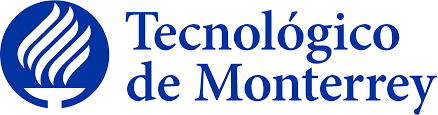

### Fundamentación de robótica (TE3001B)

## Actividad 2 (Análisis de Robot lineal de 3GDL)

### Pamela Hernández Montero A01736368

**Objetivo**

Obtener el vector de velocidad lineal y angular de un robot lineal de 3GDL en MATLAB.

**Introducción**

Un robot lineal de 3GDL (grados de libertad) es un sistema mecánico que puede moverse en tres direcciones principales en el espacio tridimensional. Estos grados de libertad corresponden a los ejes x, y, y z. En estos casos el vector de velocidad de un robot de este tipo consiste en dos componentes principales: la velocidad lineal, que describe la tasa de cambio del desplazamiento en el espacio, y la velocidad angular, que indica la tasa de cambio de orientación del robot. La siguiente imagen corresponde al robot de 3GDL que se analizara en este trabajo:

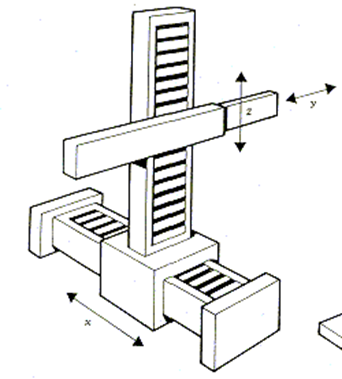

Como se puede observar este robot tiene una estructura que permite el movimiento en tres ejes diferentes: x, y y z (etiquetados con flechas). La base rectangular sólida sostiene tres componentes lineales, cada uno moviéndose a lo largo de un eje específico.

Para este analisis las variables simbólicas solo se consideran las longitudes con respecto al tiempo de cada eje debido a que el movimiento de cada componente lineal corresponde a una junta prismatica.

%Limpieza de pantalla
clear all
close all
clc

%Variables simbólicas
syms l1(t) l2(t) l3(t) t

% Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP = [1 1 1];
% Vector de coordenadas articulares
Q = [l1(t), l2(t), l3(t)];
disp('Coordenadas generalizadas:');pretty(Q);

Coordenadas generalizadas:
(l1(t), l2(t), l3(t))



% Velocidades generalizadas
Qp = diff(Q, t);
disp('Velocidades generalizadas:');pretty(Qp);

Velocidades generalizadas:
/  d         d         d       \
| -- l1(t), -- l2(t), -- l3(t) |
\ dt        dt        dt       /



%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

Para el analisis de cada articulacion es necesario comprender su marco de referencia local que recae en la base de la primer junta prismatica, generalmente se estrablece que el movimiento se encuentra en el eje Z. Para alinear con la junta 2 es necesario rotar -90 grados al rededor de Y .

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0 ; 0; l1];
%Matriz de rotación de la junta 1 respecto a 0 
R(:,:,1)= [0  0 -1 ;
           0  1  0;
           1  0  0];

Una vez alineada la junta 2 como existe otra junta el sistema de referencias vuelve a ajustarse en direccion al movimiento de la junta 3 rotando -90 grados al rededor de X.

%Articulación 2 
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [0; l3 ; l2];
%Matriz de rotación de la junta 2 respecto a 1  
R(:,:,2)= [1  0 0;
           0  0 1;
           0 -1 0];

Para la ultima junta no se rota el marco referencial debido a que no existe otro movimiento en el determinando una matriz identidad.

%Articulación 3 
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [0; 0 ;0];
%Matriz de rotación de la junta 3 respecto a 2   
R(:,:,3)= [1  0 0;
           0  1 0;
           0  0 1];

Las siguientes lineas se crean para asignar valores iniciales a las matrices y vectores a utilizar.

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);
%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 

En el siguiente ciclo se calcula la matriz de transformación global de cada articulación.

for i = 1:GDL
    i_str= num2str(i);
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))
    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
end

Matriz de Transformación global T1


/ 0, 0, -1,   0   \
|                 |
| 0, 1,  0,   0   |
|                 |
| 1, 0,  0, l1(t) |
|                 |
\ 0, 0,  0,   1   /



Matriz de Transformación global T2


/ 0, 1, 0, -l2(t) \
|                 |
| 0, 0, 1,  l3(t) |
|                 |
| 1, 0, 0,  l1(t) |
|                 |
\ 0, 0, 0,    1   /



Matriz de Transformación global T3


/ 0, 1, 0, -l2(t) \
|                 |
| 0, 0, 1,  l3(t) |
|                 |
| 1, 0, 0,  l1(t) |
|                 |
\ 0, 0, 0,    1   /



Antes de continuar con la explicación es importante destacar que la matriz de transformación local es esencial para calcular la matriz de transformación global, debido a que se obtiene concatenando todas las transformaciones locales desde la base del robot hasta el extremo.

1. Matriz de Transformación global T1:

   -  La posición y orientación del extremo del robot en el espacio global es directamente determinada por la transformación local, ya que no hay ninguna articulación anterior que modifique esta posición.

2. Matriz de Transformación global T2:

   - La matriz depende de la posición y orientación de la primera junta y la tercera, ya que estas juntas influye directamente en la posición del extremo del robot.

3. Matriz de Transformación global T3:

   -  La matriz T3 depende de la posición y orientación tanto de la primera como de la segunda junta, ya que ambas articulaciones afectan la posición final del extremo del robot.

Para obtener las velocidades lineales y  angulares se utilizan las siguientes formulas:

$J_{\textrm{vi}} =Z_{i-1}$ (Jacobianio lineal)

$J_{\omega i} =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$ (Jacobiano angular)

%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
V=simplify (Jv_a*Qp');
disp('Velocidad lineal obtenida mediante el Jacobiano lineal');pretty(V);

Velocidad lineal obtenida mediante el Jacobiano lineal
/   ________ \
|    d       |
| - -- l2(t) |
|   dt       |
|            |
|  ________  |
|   d        |
|  -- l3(t)  |
|  dt        |
|            |
|  ________  |
|   d        |
|  -- l1(t)  |
\  dt        /



Las velocidades lineales obtenidas mediante el Jacobiano lineal describe cómo los cambios en las articulaciones del robot afectan la rapidez con la que se mueve el extremo del robot en diferentes direcciones.

W=simplify (Jw_a*Qp');
disp('Velocidad angular obtenida mediante el Jacobiano angular');pretty(W);

Velocidad angular obtenida mediante el Jacobiano angular
/ 0 \
|   |
| 0 |
|   |
\ 0 /



Por otro lado, la respuesta de velocidad angular en 0 a todos los ejes representa que, en este caso las velocidades angulares de las juntas del robot no tienen un impacto directo debido a que estan configuradas de tal manera que su movimiento no afecta la velocidad de rotación del extremo del robot en torno a los ejes x, y, y z. 